# Bulk iHUMAN Gene KO Analysis

**Author:** Scott Campit

## Summary

This script computes bulk differentially acitve reactions between epithelial and mesenchymal cells in the RECON1 metabolic model.

clear all;

## 1. Load data

We'll load the iHUMAN data obtained from three independent EMT studies induced with TGF-B:

- GSE17518 (Thannickal transcriptomics)

- GSE17708 (Keshamouni transcriptomics)

- Garcia proteomics data

**Note** that the primary assumption is that mesenchymal cells are more likely to be found in later time points than earlier ones.

Let's first load RECON1 reaction IDs.

load ihuman_model_data_dec2020.mat ihuman_hams
rxn_ids = string([ihuman_hams.rxns, ihuman_hams.rxnNames, ihuman_hams.subSystems]);

### A. GSE17518

Note that this experiment compared hour 72 versus hour 0.

#### i. Load data

First we'll load all of the data as a single vector. 

GSE17518_labels = "72/0hrs";
datapath = dir(fullfile("D:/Analysis/EMT/gse17518/ihuman/", "*.mat"));
load(strcat(datapath.folder, '\', datapath.name));
GSE17518_grate = cobra_cell.geneko;

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

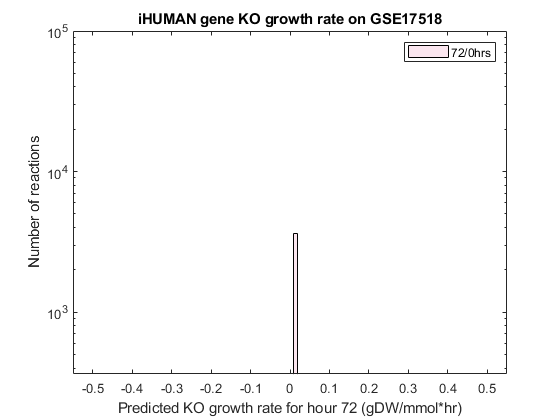

figure;
h1 = histogram(GSE17518_grate, 100);
set(h1, 'facecolor', "#f9d5e5");
legend(GSE17518_labels);
set(gca, 'YScale', 'log')
title("iHUMAN gene KO growth rate on GSE17518");
xlabel("Predicted KO growth rate for hour 72 (gDW/mmol*hr)");
ylabel("Number of reactions");

#### iii. Identify which reactions are potential outliers

It looks like there are a couple of reactions that have a flux value < -5 gDW/mmol*hr. Let's see which reaction are highly active.

idx = find(GSE17518_grate < -5);
tmp_flux = GSE17518_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

Just to be safe, let's also try to find the reactions that may have a highly positive flux value.

idx = find(GSE17518_grate > 5);
tmp_flux = GSE17518_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

#### iv. Takeaways

It looks like there are no significant outliers in this dataset.

### B. GSE17708

#### i. Load data

First we'll load all of the data as a single dataframe.

GSE17708_labels = string();
datapath = dir(fullfile("D:/Analysis/EMT/gse17708/ihuman/", "*.mat"));
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    GSE17708_grate(:, i) = cobra_cell.geneko;
    GSE17708_labels(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

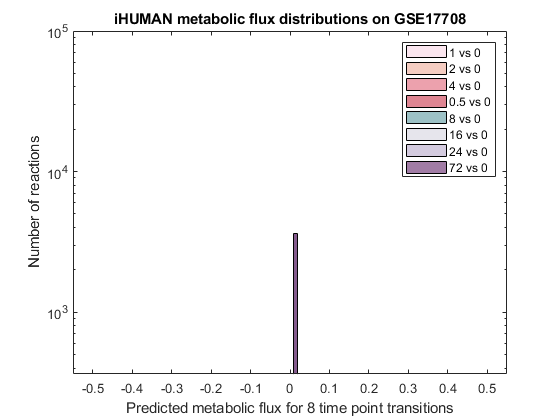

figure;
h1 = histogram(GSE17708_grate(:, 1), 100);
hold on;
h2 = histogram(GSE17708_grate(:, 2), 100);
hold on;
h3 = histogram(GSE17708_grate(:, 3), 100);
hold on;
h4 = histogram(GSE17708_grate(:, 4), 100);
hold on;
h5 = histogram(GSE17708_grate(:, 5), 100);
hold on;
h6 = histogram(GSE17708_grate(:, 6), 100);
hold on;
h7 = histogram(GSE17708_grate(:, 7), 100);
hold on;
h8 = histogram(GSE17708_grate(:, 8), 100);

set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");

set(h5, 'facecolor', "#5b9aa0");
set(h6, 'facecolor', "#d6d4e0");
set(h7, 'facecolor', "#b8a9c9");
set(h8, 'facecolor', "#622569");

legend(GSE17708_labels);
set(gca, 'YScale', 'log')
title("iHUMAN metabolic flux distributions on GSE17708");
xlabel("Predicted metabolic flux for 8 time point transitions");
ylabel("Number of reactions");

#### iii. Identify which reactions are potential outliers

It looks like there are a couple of reactions that have a flux value < -5 gDW/mmol*hr. Let's see which reaction are highly active.

idx = find(any(GSE17708_grate < -5, 2));
tmp_flux = GSE17708_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

Just to be safe, let's also try to find the reactions that may have a highly positive flux value.

idx = find(any(GSE17708_grate > 5, 2));
tmp_flux = GSE17708_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

#### iv. Takeaways

For GSE17708, the same reactions seem to be causing the same problems, suggesting this is simply an artifact of RECON1.

### C. Garcia proteomics

#### i. Load data

First we'll load all of the data as a single dataframe.

datapath = dir(fullfile("D:/Analysis/EMT/garcia/ihuman/", "*.mat"));
Garcia_labels = string();
for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    Garcia_grate(:, i) = cobra_cell.geneko;
    Garcia_labels(i) = cobra_cell.id;
end

#### ii. Visualize the flux data

Let's now visualize the metabolic flux data using a histogram.

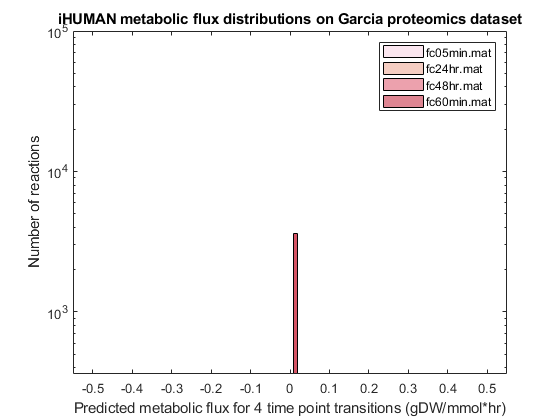

figure;
h1 = histogram(Garcia_grate(:, 1), 100);
hold on;
h2 = histogram(Garcia_grate(:, 2), 100);
hold on;
h3 = histogram(Garcia_grate(:, 3), 100);
hold on;
h4 = histogram(Garcia_grate(:, 4), 100);


set(h1, 'facecolor', "#f9d5e5");
set(h2, 'facecolor', "#eeac99");
set(h3, 'facecolor', "#e06377");
set(h4, 'facecolor', "#c83349");

legend(Garcia_labels);
set(gca, 'YScale', 'log')
title("iHUMAN metabolic flux distributions on Garcia proteomics dataset");
xlabel("Predicted metabolic flux for 4 time point transitions (gDW/mmol*hr)");
ylabel("Number of reactions");

#### iii. Identify which reactions are potential outliers

It looks like there are a couple of reactions that have a flux value < -5 gDW/mmol*hr. Let's see which reaction are highly active.

idx = find(any(Garcia_grate < -5, 2));

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

tmp_flux = Garcia_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

Just to be safe, let's also try to find the reactions that may have a highly positive flux value.

idx = find(any(Garcia_grate > 5, 2));
tmp_flux = Garcia_grate(idx, :)
tmp_ids = rxn_ids(idx, :)

#### iv. Takeaways

For the Garcia proteomics dataset, the same reactions seem to be causing the same problems, further supporting the notion that this is simply an artifact of RECON1.

### D. Major takeaways from all of the datasets

It appears that specific transport and exchange reactions that have fluxes greater than 5 or less than negative 5 are always skewing the data distribution. These need to be filtered out from downstream analyses.

## 2. Compute differentially active metabolic fluxes

### A. Concatenate the data

We'll construct 1 large dataframe of all reactions. We'll also ensure the absolute value for the reactions is taken to remove reaction directionality - just consider magnitude of activity.

data = [GSE17518_grate', GSE17708_grate, Garcia_grate];
rxn_ids = string([ihuman_hams.rxns, ihuman_hams.rxnNames, ihuman_hams.subSystems]);

Remove reactions that have fluxes greater than 5.

idx = find(any(data > 5, 2));
data(idx, :) = [];
rxn_ids(idx, :) = [];

Now remove reactions that have fluxes less than -5.

idx = find(any(data < -5, 2));
data(idx, :) = [];
rxn_ids(idx, :) = [];

If you want, only consider the absolute magnitude of the data.

data = abs(data);

### B. Visualize the flux data distribution across all studies

To get a sense of the entire dataset, let's visualize the entire flux distribution.

figure;
histogram(data, 100);
set(gca, 'YScale', 'log')
title("iHUMAN flux distribution across all studies");
xlabel("Absolute value of metabolic fluxes (gDW/mmol*hr)");
ylabel("Number of reactions");

### C. Identify up- and downregulated metabolic reactions

#### i. Compute mean flux across all experiments for each reaction

We'll now take the average flux value across all experiments for each reaction

%mu = median(data, 2);
mu = mean(data, 2);

#### ii. Compute standard deviation across all experiments for each reaction

We'll also take the standard deviation across all experiments for each reaction

%sigma = (1.4826*mad(data, [], 'all'));
sigma = std(data, [], 2);

#### iii. Compute the Robust Z-score matrix

Now let's take the Z-score for all reactions using the mean and standard deviation computed above.

zmat = (data - mu) ./ sigma;

#### iv. Compute p-values for metabolic fluxes

Transform the Z-scores into p-values.

pvalue = normpdf(zmat);

#### v. Visualize the data distribution

figure;
histogram(zmat, 100);
set(gca, 'YScale', 'log')
title("iHUMAN Z-score distribution");
xlabel("Z-score");
ylabel("Number of reactions");

#### vi. Get final reaction table

First load the reaction ids.

%load recon1.mat
%rxn_ids = string([recon1.rxns, recon1.rxnNames, recon1.subSystems]);
sample_ids = [GSE17518_labels, GSE17708_labels, Garcia_labels];

Next, get the index for reactions to remove.

idx1 = find(all(isnan(zmat), 2));
zmat(idx1, :) = [];
pvalue(idx1, :) = [];
rxn_ids(idx1, :) = [];

mask = pvalue > 0.05;
idx = all(mask, 2);
rxn_ids(idx, :) = [];
zmat(idx, :) = [];
pvalue(idx, :) = [];
mask(idx, :) = [];
zmat(mask) = NaN;

#### vii. Visualize reactions that have significant hits as a heatmap

figure;
heatmap(zmat, ...
    'Colormap', redbluecmap);
ax = gca;
ax.XData = sample_ids;
ax.YData = rxn_ids(:, 1);
title("Signficantly active metabolic reactions")

#### viii. Visualize reactions that have significant hits as a clustergram

zmat(isnan(zmat)) = 0;
d = clustergram(zmat, ...
    'RowLabels', rxn_ids(:, 1), ...
    'ColumnLabels', sample_ids, ...
    'Colormap', redbluecmap)
d.Dendrogram = 1;